Problem 1:

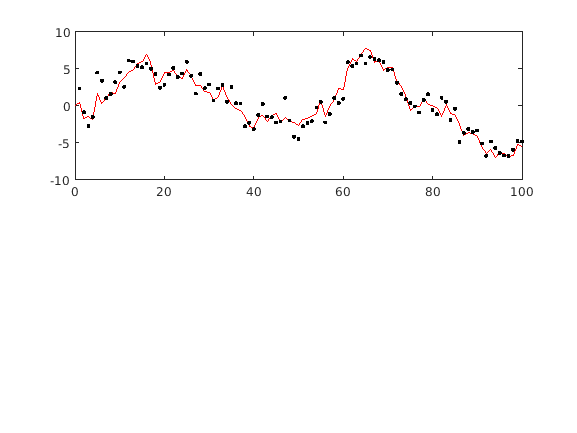

% generate the data
rng('default'); rng(0);
nk=100;
x0=0; Q=1; R=1;
X=zeros(1,nk);Y=zeros(1,nk);
x=x0;
for k=1:nk
    x=x+sqrt(Q)*randn; X(k)=x;
    Y(k)=x+sqrt(R)*randn;
end
figure(1)
subplot(211)
plot(0:nk,[x0,X],'r-',1:nk,Y,'k.')

%phiT=@(theta) phi1(theta,Y);

% EM algorithm
N_EM=30;           % number of EM iterations
theta_EM=[0.5;0.5];      % starting guess for R and Q
A=1; H=1; %Q=1;     % known model values
theta_EM_iterands=repmat(theta_EM,1,N_EM+1);   % preallocate 
for i=1:N_EM
    [Sigma,Phi,B,C,D]=EMQ_params(theta_EM,Y);
    theta_EM(1) = D-H*B'-B*H'+H*Sigma*H';         %R
    theta_EM(2) = Sigma - C*A' - A*C' + A*Phi*A;  %Q
    theta_EM_iterands(:,i+1)=theta_EM;
end
theta_EM

theta_EM =     0.8591
    1.3646


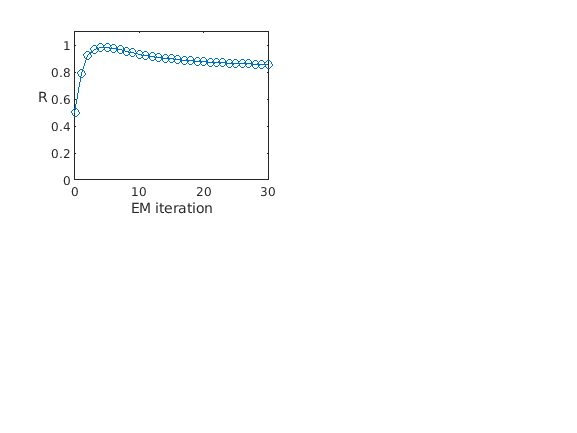


figure(2)
subplot(221)
plot(0:N_EM,theta_EM_iterands(1,:),'-o')
axis([0 N_EM 0 1.1])
xlabel('EM iteration'), ylabel('R','rot',0,'horiz','r')

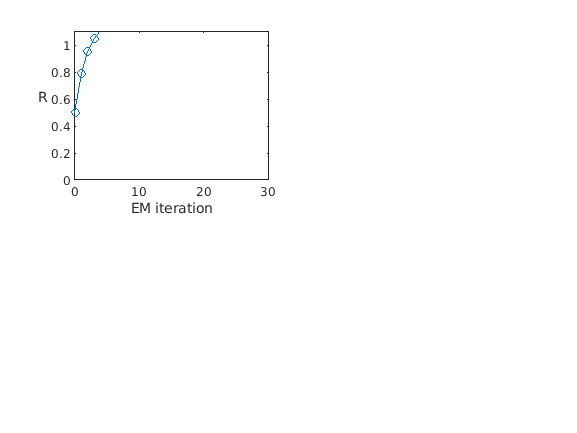

figure(3)
subplot(221)
plot(0:N_EM,theta_EM_iterands(2,:),'-o')
axis([0 N_EM 0 1.1])
xlabel('EM iteration'), ylabel('R','rot',0,'horiz','r')

Problem 2:

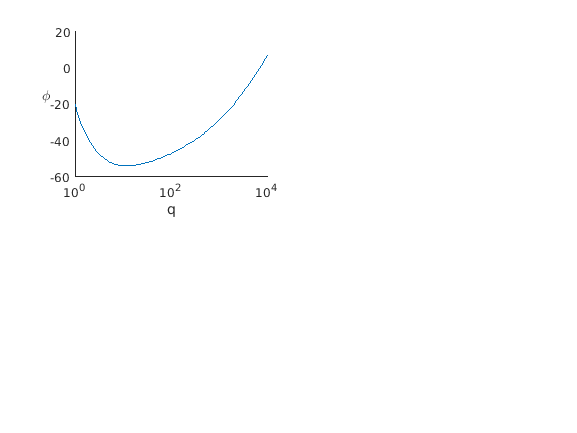

dt=0.02; t=0:dt:2; nt=length(t); X=sin(pi*t);
rng('default'); Y=X(2:end)+0.1*randn(1,nt-1);

R=0.01; m0=[0;pi]; P0=0.1*eye(2);
A=[1 dt;0 1]; Qd=[dt^3/3 dt^2/2;dt^2/2 dt]; H=[1 0];
qq=logspace(0,4,100); phi=nan(size(qq));
for iq=1:length(qq)
    phi(iq)=kf(A,qq(iq)*Qd,H,R,m0,P0,Y);   % function is at end of script
end
semilogx(qq,phi)
box off, xlabel('q'), ylabel('\phi','rot',0)


%find minima of q
phi2T=@(q) kf(A,q*Qd,H,R,m0,P0,Y);
q_MAP=fminbnd(phi2T,1,100)

q_MAP = 12.2515

Functions

function val=phi1(theta,Y)
DT = 0.02;
A = [1 DT;0 1];
H = [1 0];
Q = theta*[1/3*DT^3 1/2*DT^2; 1/2*DT^2 DT];
A=1; Q=1;  R=1; m=[0;pi]; P=[0.1 0;0 0.1];
val=0;  % flat prior; any constant will do
for k=1:size(Y,2)
    m=A*m; P=A*P*A'+Q;  % KF prediction
    v=Y(:,k)-H*m; S=H*P*H'+R;
    val=val+0.5*v'/S*v+sum(log(diag(chol(2*pi*S))));
    K=P*H'/S; m=m+K*v; P=P-K*S*K';  % KF update
end
end

function [Sigma,Phi,B,C,D]=EMQ_params(theta,Y)
A=1; Q=theta(2); 
H=1; R=theta(1); m0=0; P0=0;
nk=size(Y,2);
kf_m=zeros(1,nk); kf_P=zeros(1,1,nk); % preallocate
m=m0; P=P0;
for k=1:nk % Kalman filter
    kf_m(:,k)=m; kf_P(:,:,k)=P;  % save m & P at time k-1
    m=A*m; P=A*P*A'+Q;
    S=H*P*H'+R;
    K=P*H'/S;
    m=m+K*(Y(:,k)-H*m);
    P=P-K*S*K';
end
Sigma=P+m*m'; Phi=zeros(size(P)); C=zeros(size(P));
B=zeros(size(R)); D=zeros(size(R));
for k=nk-1:-1:0    % RTS smoother
    mp=A*kf_m(:,k+1);
    Pp=A*kf_P(:,:,k+1)*A'+Q;
    G=kf_P(:,:,k+1)*A'/Pp;
    mm=m; PP=P; 
    m=kf_m(:,k+1)+G*(m-mp);
    P=kf_P(:,:,k+1)+G*(P-Pp)*G';
    Phi=Phi+P+m*m';
    B=B+Y(:,k+1)*mm';
    C=C+PP*G'+mm*m';
    D=D+Y(:,k+1)*Y(:,k+1)';
    if k>0, Sigma=Sigma+P+m*m'; end
end
Sigma=Sigma/nk; Phi=Phi/nk; B=B/nk; C=C/nk; D=D/nk;
end

Kalman filter used in problems 2-4. It also computes the "energy" for parameter identification.

function [phi,mm]=kf(A,Q,H,R,m0,P0,Y)
nk=size(Y,2);
mm=repmat(m0,1,nk);
m=m0; P=P0; phi=0;
for k=1:nk
    m=A*m; P=A*P*A'+Q;
    v=Y(:,k)-H*m; S=H*P*H'+R;
    phi=phi+v'/S*v/2+sum(log(diag(chol(2*pi*S))));
    K=P*H'/S; m=m+K*v; P=P-K*S*K';
    mm(:,k)=m;
end
end